# Demonstration of Clustering Functions in scGEApp

## Load example data

cdgea; % set working directory
% load('example_data/example10xdata2.mat','X','genelist');
[X,genelistx]=sc_readfile('example_data/GSM3204304_P_P_Expr_999cells.csv');

Reading example_data/GSM3204304_P_P_Expr_999cells.csv ...... done.


[Y,genelisty]=sc_readfile('example_data/GSM3204305_P_N_Expr_999cells.csv');

Reading example_data/GSM3204305_P_N_Expr_999cells.csv ...... done.


[X,genelistx]=sc_selectg(X,genelistx,3,1);
[Y,genelisty]=sc_selectg(Y,genelisty,3,1);

## Intersection of common genes in X, Y and Z

[genelist]=intersect(genelistx,genelisty,'stable');
% Remove genes encoded in the mitochondrial genome
i=startsWith(genelist,'MT-');
genelist(i)=[];
[~,i1]=ismember(genelist,genelistx);
[~,i2]=ismember(genelist,genelisty);
X=X(i1,:); genelistx=genelist;
Y=Y(i2,:); genelisty=genelist;

## Label cells

cellidx=[1*ones(size(X,2),1); 2*ones(size(Y,2),1)];

## Cluster cells using SIMLR

C=sc_cluster([X Y],'type','simlr');

To specify k, use RUN_SIMLR(X,k).
Iteration 10: error is 1.7245
Iteration 20: error is 1.6259
Iteration 30: error is 1.3316
Iteration 40: error is 0.8594
Iteration 50: error is 0.75307
Iteration 60: error is 0.68778
Iteration 70: error is 0.64046
Iteration 80: error is 0.60484
Iteration 90: error is 0.57663
Iteration 100: error is 0.55388
Iteration 110: error is 0.53515
Iteration 120: error is 0.51932
Iteration 130: error is 0.5058
Iteration 140: error is 0.49411
Iteration 150: error is 0.48368
Iteration 160: error is 0.47456
Iteration 170: error is 0.46636
Iteration 180: error is 0.459
Iteration 190: error is 0.45235
Iteration 200: error is 0.44628
Iteration 210: error is 0.44071
Iteration 220: error is 0.43564
Iteration 230: error is 0.43093
Iteration 240: error is 0.42656
Iteration 250: error is 0.42251
Iteration 260: error is 0.41861
Iteration 270: error is 0.41494
Iteration 280: error is 0.4115
Iteration 290: error is 0.40829
Iteration 300: error is 0.40527
Iteration 310: error is

## Plot the clustering result

s=sc_tsne([X Y],2,false,true,false);   % s=sc_tsne(X,ndim,plotit,donorm,dolog1p);

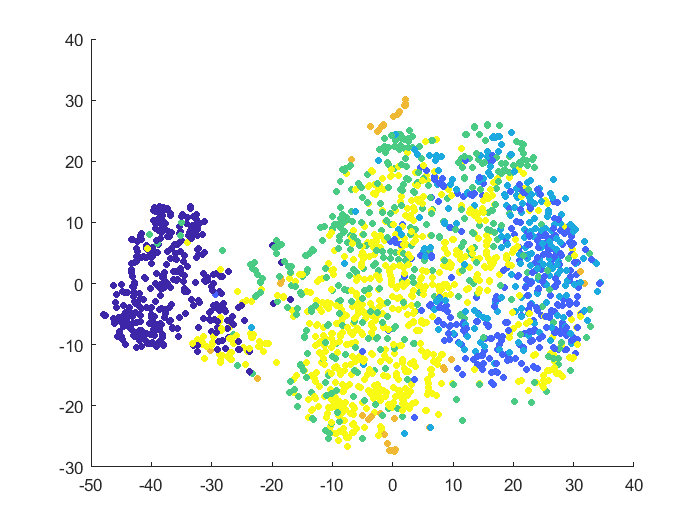

figure;
scatter(s(:,1),s(:,2),20,C,'filled')

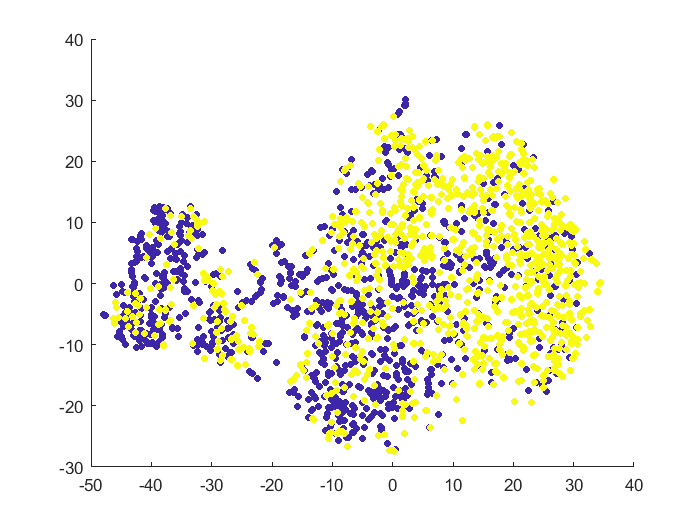


figure;
scatter(s(:,1),s(:,2),20,cellidx,'filled')

## Using SC3 example data yan.csv

[X,genelist]=sc_readtsvfile('example_data/yan.csv');

Reading example_data/yan.csv ...... done.


t=readtable('example_data\yan_celltype.txt');
celltypelist=string(t.cell_type1);
rng(235); showlegend=true;
% rng(111); showlegend=false;
% rng(113); showlegend=true;

s=sc_tsne(X,2);
c1=sc_sc3(X,6);

CLUSTER ENSEMBLES using CSPA
wgraph: writing graph0
 
C:\Users\jcai\Documents\GitHub\scGEATool\thirdparty\ClusterPack>pmetis graph0 6  
********************************************************************** 
  METIS 3.0   Copyright 1997, Regents of the University of Minnesota 
 
Graph Information --------------------------------------------------- 
  Name: graph0, #Vertices: 90, #Edges: 1111, #Parts: 6 
 
Recursive Partitioning... ------------------------------------------- 
  6-way Edge-Cut: 16923384, Balance:  1.13 
 
Timing Information -------------------------------------------------- 
  I/O:          		   0.005 
  Partitioning: 		   0.001   (PMETIS time) 
  Total:        		   0.006 
********************************************************************** 
sgraph: partgraph1000.bat completed - loading graph0.part.6
clusterensemble: cspa at 0.83027
CLUSTER ENSEMBLES using HGPA
wgraph: writing graph2
wgraph: 90 vertices and 108 non-zero hyperedges
 
C:\Users\jcai\Documents\GitHub\scGEA

c2=run_simlr(X,6);

Iteration 10: error is 0.21153
Iteration 20: error is 1.1375
Iteration 30: error is 0.62867
Iteration 40: error is 0.25251
Iteration 50: error is 0.15781
Iteration 60: error is 0.26267
Iteration 70: error is 0.10414
Iteration 80: error is 0.074384
Iteration 90: error is 0.33669
Iteration 100: error is 0.35016
Iteration 110: error is 0.17267
Iteration 120: error is 0.27486
Iteration 130: error is 0.26362
Iteration 140: error is 0.10059
Iteration 150: error is 0.14544
Iteration 160: error is 0.073536
Iteration 170: error is 0.62833
Iteration 180: error is 0.09553
Iteration 190: error is 0.04823
Iteration 200: error is 0.16277
Iteration 210: error is 0.30459
Iteration 220: error is 0.13781
Iteration 230: error is 0.059532
Iteration 240: error is 0.049503
Iteration 250: error is 0.048301
Iteration 260: error is 0.079106
Iteration 270: error is 0.072208
Iteration 280: error is 0.067198
Iteration 290: error is 0.10873
Iteration 300: error is 0.03513
Iteration 310: error is 0.16895
Iteration 

c3=run_soptsc(X,'k',6);

Iter  Err
1, 6.867832
2, 5.876795
3, 5.042887
4, 4.362326
5, 3.807127
6, 3.351183
7, 2.973775
8, 2.658954
9, 0.711817
10, 0.112101
11, 0.103572
12, 0.098797
13, 0.093055
14, 0.087015
15, 0.081145
16, 0.075632
17, 0.070527
18, 0.062194
19, 0.050105
20, 0.034833
21, 0.017597
22, 0.019880



% Result of SC3 R
load example_data/sc3_results.txt
c0=sc3_results;

% Compare clustering results between SC3/R vs SC3, SIMILR and SoptSC
Cal_NMI(c0,c1)

ans = 0.9205

Cal_NMI(c0,c2)

ans = 0.8200

Cal_NMI(c0,c3)

ans = 0.5464

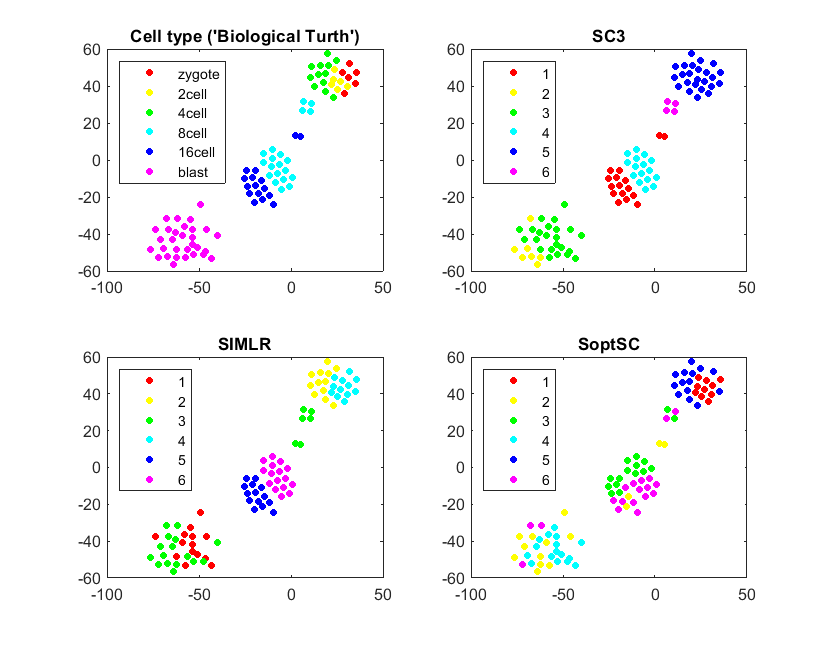



fh=figure; 
subplot(2,2,1)
gscatter(s(:,1),s(:,2),celltypelist)
if showlegend, legend('Location','northwest'); else, legend off; end
title('Cell type (''Biological Turth'')')

subplot(2,2,2)
gscatter(s(:,1),s(:,2),c1)
if showlegend, legend('Location','northwest'); else, legend off; end
title('SC3')

subplot(2,2,3)
gscatter(s(:,1),s(:,2),c2)
if showlegend, legend('Location','northwest'); else, legend off; end
title('SIMLR')

subplot(2,2,4)
gscatter(s(:,1),s(:,2),c3)
if showlegend, legend('Location','northwest'); else, legend off; end
title('SoptSC')
fh.Position=[fh.Position(1) fh.Position(2)-100 fh.Position(3)+100 fh.Position(4)+100];

## The End